# Titanic

Date: 3/2017

Data Source: Kaggle.com

## Understand Business Goals 

Objectives:

- Survived is the response

## Prepare and Understand Data

Clean Up

clear
clc
close all


Load Data

data = readtable('train.csv','Format','%f%f%f%q%C%f%f%f%q%f%q%C');
predictData = readtable('test.csv','Format','%f%f%q%C%f%f%f%q%f%q%C');

Statistical summaries

summary(data);


Variables:

    PassengerId: 891×1 double

        Values:

            Min         1          
            Median    446          
            Max       891          

    Survived: 891×1 double

        Values:

            Min       0         
            Median    0         
            Max       1         

    Pclass: 891×1 double

        Values:

            Min       1       
            Median    3       
            Max       3       

    Name: 891×1 cell array of character vectors

    Sex: 891×1 categorical

        Values:

            female    314  
            male      577  

    Age: 891×1 double

        Values:

            Min            0.42 
            Median         28   
            Max            80   
            NumMissing     177  

    SibSp: 891×1 double

        Values:

            Min       0      
            Median    0      
   

summary(predictData);


Variables:

    PassengerId: 418×1 double

        Values:

            Min          892       
            Median    1100.5       
            Max         1309       

    Pclass: 418×1 double

        Values:

            Min       1       
            Median    3       
            Max       3       

    Name: 418×1 cell array of character vectors

    Sex: 418×1 categorical

        Values:

            female    152  
            male      266  

    Age: 418×1 double

        Values:

            Min            0.17 
            Median         27   
            Max            76   
            NumMissing     86   

    SibSp: 418×1 double

        Values:

            Min       0      
            Median    0      
            Max       8      

    Parch: 418×1 double

        Values:

            Min       0      
            Median    0      
            Max

Feature Engineering (Drop/Create/Convert/Complete)

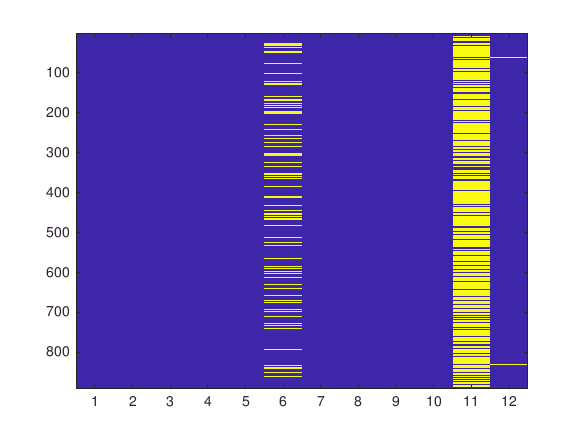

% Check for missing data
if(nnz(ismissing(data)))
    figure
    imagesc(ismissing(data))
    ax = gca;
    varsTrain = data.Properties.VariableNames;
    ax.XTick = 1:length(varsTrain);
%     ax.XTickLabel = vars;
%     ax.XTickLabelRotation = 90;
end

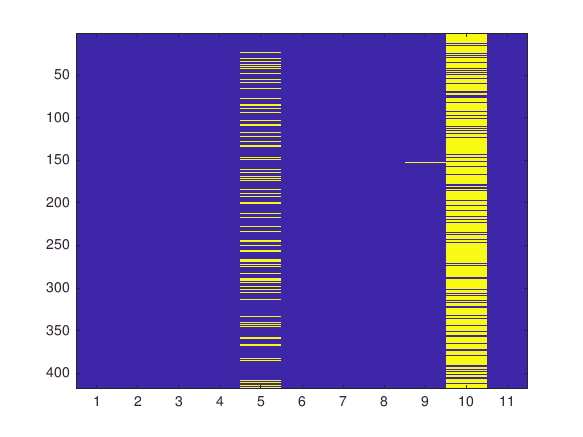

% Check for missing predictData data
if(nnz(ismissing(predictData)))
    figure
    imagesc(ismissing(predictData))
    ax = gca;
    varsTest = predictData.Properties.VariableNames;
    ax.XTick = 1:length(varsTest);
%     ax.XTickLabel = vars;
%     ax.XTickLabelRotation = 90;
end

% Remove
data(:,{'Name','PassengerId','Cabin','Ticket'}) = [];
predictData(:,{'Name','PassengerId','Cabin','Ticket'}) = [];
% Replace
data.Age(isnan(data.Age)) = nanmean(data.Age);
data.Embarked(isundefined(data.Embarked)) = mode(data.Embarked);
predictData.Age(isnan(predictData.Age)) = nanmean(predictData.Age);
predictData.Fare(isnan(predictData.Fare)) = 0;
% Convert
data.Embarked = double(data.Embarked);
data.Sex = double(data.Sex);
predictData.Embarked = double(predictData.Embarked);
predictData.Sex = double(predictData.Sex);
% Create
data.AgeGroup = double(discretize(data.Age, [0 10 20 65 80],'categorical',{'child','teen','adult','senior'}));
predictData.AgeGroup = double(discretize(predictData.Age, [0 10 20 65 80],'categorical',{'child','teen','adult','senior'}));
% Double check missing data
if ((nnz(ismissing(data))+nnz(ismissing(predictData)))~=0)
    warning('There are missing data. Check!')
end

Exploratory Analysis and Visualizations

% Variables with a small set of unique values
grpstats(data(:,{'Survived','Sex'}),'Sex')

ans = 2×3 table
         Sex    GroupCount    mean_Survived
         ___    __________    _____________

    1    1      314           0.74204      
    2    2      577           0.18891      


grpstats(data(:,{'Survived','Pclass'}),'Pclass')

ans = 3×3 table
         Pclass    GroupCount    mean_Survived
         ______    __________    _____________

    1    1         216           0.62963      
    2    2         184           0.47283      
    3    3         491           0.24236      


grpstats(data(:,{'Survived','Embarked'}),'Embarked')

ans = 3×3 table
         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    1    1           168           0.55357      
    2    2            77           0.38961      
    3    3           646           0.33901      


grpstats(data(:,{'Survived','Sex','Pclass'}),{'Sex','Pclass'})

ans = 6×4 table
           Sex    Pclass    GroupCount    mean_Survived
           ___    ______    __________    _____________

    1_1    1      1          94           0.96809      
    1_2    1      2          76           0.92105      
    1_3    1      3         144               0.5      
    2_1    2      1         122           0.36885      
    2_2    2      2         108           0.15741      
    2_3    2      3         347           0.13545      


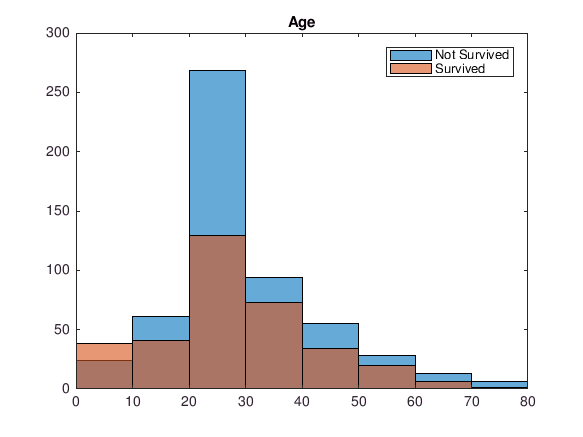

% Variables wtih a large set of unique values
figure
histogram(data.Age(data.Survived==0),0:10:80)
title('Age')
hold on
histogram(data.Age(data.Survived==1),0:10:80)
legend('Not Survived','Survived')

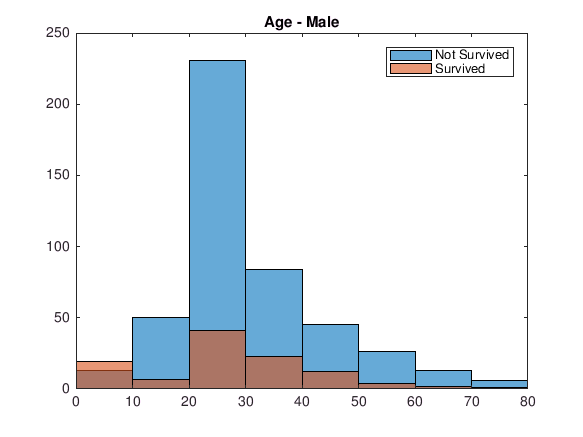


figure
histogram(data.Age(data.Survived==0 & data.Sex==2),0:10:80)
title('Age - Male')
hold on
histogram(data.Age(data.Survived==1 & data.Sex==2),0:10:80)
legend('Not Survived','Survived')

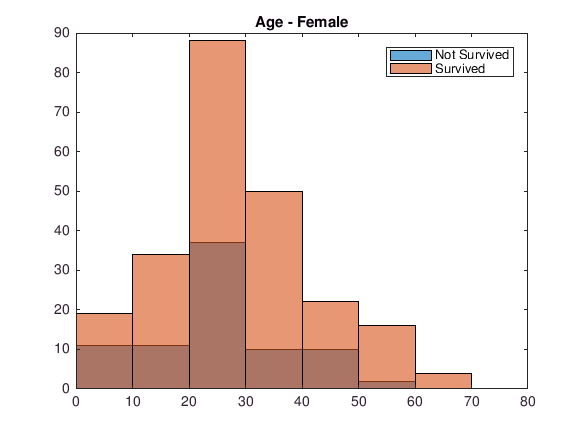


figure
histogram(data.Age(data.Survived==0 & data.Sex==1),0:10:80)
title('Age - Female')
hold on
histogram(data.Age(data.Survived==1 & data.Sex==1),0:10:80)
legend('Not Survived','Survived')

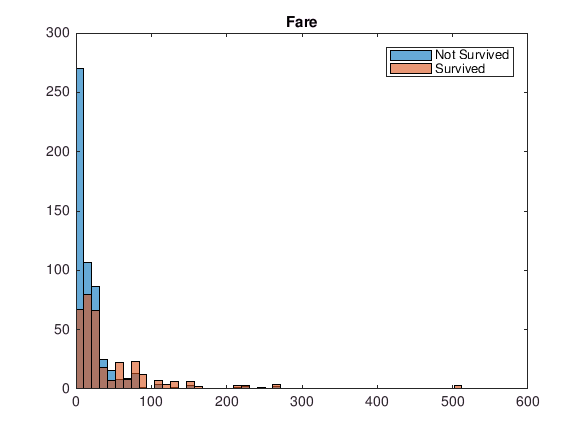


figure
histogram(data.Fare(data.Survived==0),linspace(min(data.Fare),max(data.Fare),50))
title('Fare')
hold on
histogram(data.Fare(data.Survived==1),linspace(min(data.Fare),max(data.Fare),50))
legend('Not Survived','Survived')

Correlation of variables

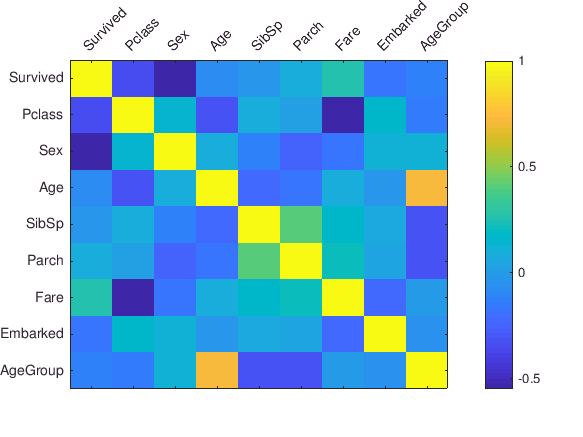

ax =   Axes with properties:

             XLim: [0.5000 9.5000]
             YLim: [0.5000 9.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1197 0.1100 0.6475 0.7516]
            Units: 'normalized'

  Show all properties


figure
imagesc(corr(data{:,:}))
colorbar
ax = gca;
vars = data.Properties.VariableNames;
ax.XTick = 1:length(vars);
ax.YTick = 1:length(vars);
ax.XTickLabel = vars;
ax.YTickLabel = vars;
ax.XTickLabelRotation = 45;
ax.XAxisLocation = 'top'

Train and Test Data Preperation

% Use cross validation partition
c = cvpartition(size(data,1),'HoldOut',0.3);
trainData = data(training(c),:);
testData = data(test(c),:);

Predict and Response Variables

responseVar = 'Survived';
predictVars = setdiff(vars,{responseVar});

PCA preperation

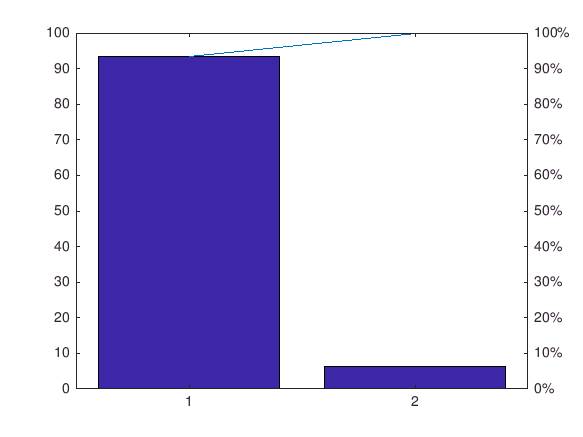

% PCA components and dimension
[pcoeff,pscore,~,~,pexp] = pca(data{:,predictVars});
pareto(pexp);

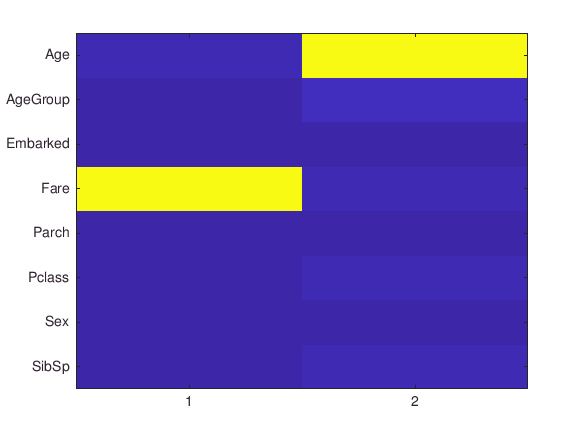

pcaD = 2;
% Show components dependancy
figure
imagesc(abs(pcoeff(:,1:pcaD)));
ax = gca;
ax.XTick = 1:pcaD;
ax.YTickLabel = predictVars;

% PCA train and test data
pcaTrain = pscore(training(c),1:pcaD);
pcaTrainResponse = data{training(c),responseVar};
pcaTest = pscore(test(c),1:pcaD);
pcaTestResponse = data{test(c),responseVar};
% Create prediction data in terms of new components
mu = mean(data{:,predictData.Properties.VariableNames});
pcaPredictData = (predictData{:,:}-mu)*pcoeff(:,1:pcaD); 

Create a structure to store all models

DA = struct;

## Choose Algorithm - Fit, Evaluate and Update Model

Classification

- K-nearest Neighbors

%%Fit
nNeighbors = 5;
mdl = fitcknn(trainData,responseVar,'NumNeighbors',nNeighbors,'Standardize',1);
DA.KNN = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.1813

% Cross Validation
kFold = 5;
mdlCV = fitcknn(trainData,responseVar,'NumNeighbors',nNeighbors,'Standardize',1,'kFold',kFold);
errCV = kfoldLoss(mdlCV)

errCV = 0.1907


%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcknn)

mdlPCA =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3620

errCV = 0.3237

DA.pcaKNN = mdlPCA;
% Feature Selection
[mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcknn)

ans = cell
    'Fare'


mdlFS =   ClassificationKNN
           PredictorNames: {'Fare'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'Fare'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3246

errCV = 0.3237

DA.fsKNN = mdlFS;
% Ensemble Leanring
mdlEn = fitensemble(trainData,responseVar,'Subspace',40,'KNN');
err = loss(mdlEn,testData)

err = 0.3078

DA.elKNN = mdlEn;
% Multiclass Method
template = templateKNN('NumNeighbors',nNeighbors,'Standardize',1);
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)

err = 0.1813

errCV = 0.1987

mdl =   ClassificationECOC
           PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 ClassificationKNN]}
               CodingName: 'onevsone'


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.1813

errCV = 0.1987

DA.mcKNN = mdl;

- Classification Trees

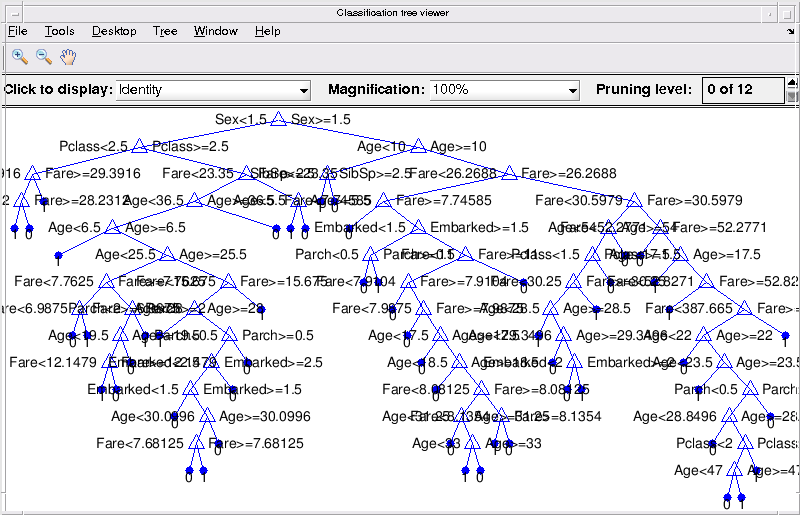

%%Fit
mdl = fitctree(trainData,responseVar);
view(mdl,'mode','graph')

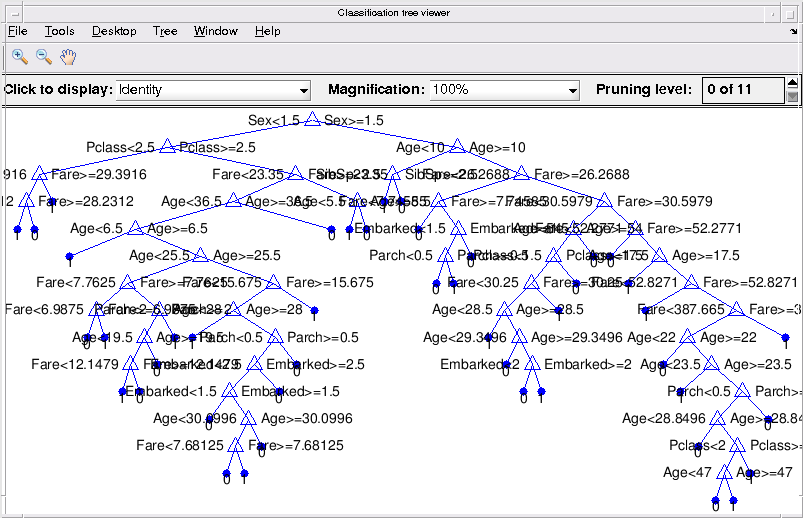

% Prune the tree
mdlPrune = prune(mdl,'Level',1);
view(mdlPrune,'mode','graph')

DA.cTree = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.1778

err = loss(mdlPrune,testData)

err = 0.1778

% Cross Validation
kFold = 5;
mdlCV = fitctree(trainData,responseVar,'kFold',kFold);
errCV = kfoldLoss(mdlCV)

errCV = 0.2003


%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitctree)

mdlPCA =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3119

errCV = 0.3622

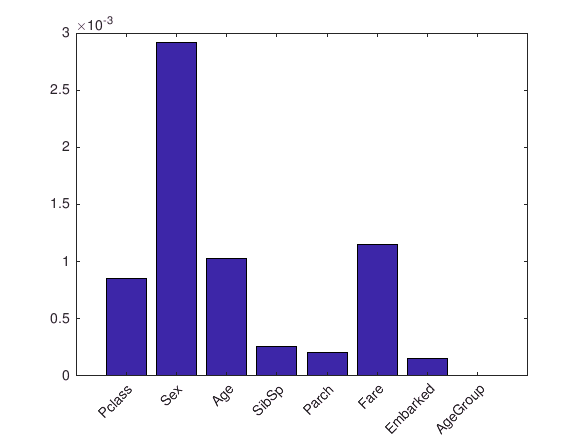

DA.pcaCTree = mdlPCA;
% Feature Importance
figure
p = predictorImportance(mdl);
bar(p);
ax = gca;
ax.XTickLabel = mdl.PredictorNames;
ax.XTickLabelRotation = 45;

toKeep = p>0.5e-3;
mdlFI = fitctree(trainData{:,toKeep},trainData{:,responseVar});
err = loss(mdlFI,testData{:,toKeep},testData{:,responseVar})

err = 0

DA.fiCTree = mdlFI;
% Feature Selection
[mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitctree)

ans = 1×4 cell array
    'Pclass'    'SibSp'    'Fare'    'Embarked'


mdlFS =   ClassificationTree
           PredictorNames: {'Embarked'  'Fare'  'Pclass'  'SibSp'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'Embarked'  'Fare'  'Pclass'  'SibSp'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3567

errCV = 0.3157

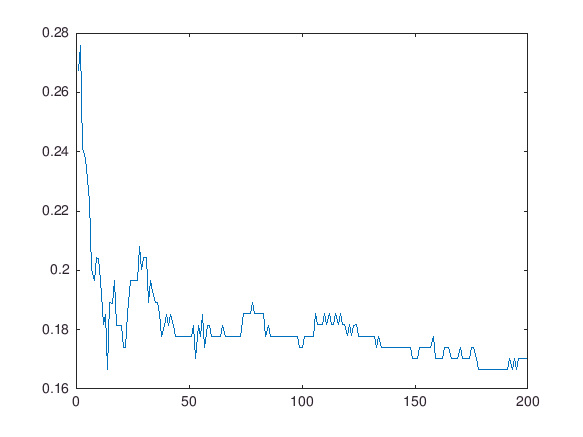

DA.fsCTree = mdlFS;
% Ensemble Learning
mdlEL = fitensemble(trainData,responseVar,'Bag',200,'Tree','Type','Classification');
figure
plot(loss(mdlEL,testData,'mode','cumulative'));

[err,idx] = min(loss(mdlEL,testData,'mode','cumulative'))

err = 0.1665

idx = 14

DA.elCTree = mdlEL;
% Multiclass Method
template = templateTree();
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)

err = 0.1778

errCV = 0.2083

mdl =   ClassificationECOC
           PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationTree]}
               CodingName: 'onevsone'


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.1778

errCV = 0.2083

DA.mcCTree = mdl;

- Gaussian Naive Bayes

%%Fit
mdl = fitcnb(trainData,responseVar,'DistributionNames','normal');
DA.NB = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.2223

% Cross Validation
kFold = 5;
mdlCV = fitcnb(trainData,responseVar,'kFold',kFold);
errCV = kfoldLoss(mdlCV)

errCV = 0.1827


%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcnb)

mdlPCA =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [0 1]
            ScoreTransform: 'none'
           NumObservations: 624
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {2×2 cell}


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3618

errCV = 0.3285

DA.pcaNB = mdlPCA;
% Feature Seletion
[mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcnb)

ans = 1×3 cell array
    'Pclass'    'Fare'    'Embarked'


mdlFS =   ClassificationNaiveBayes
            PredictorNames: {'Embarked'  'Fare'  'Pclass'}
              ResponseName: 'Survived'
     CategoricalPredictors: []
                ClassNames: [0 1]
            ScoreTransform: 'none'
           NumObservations: 624
         DistributionNames: {'normal'  'normal'  'normal'}
    DistributionParameters: {2×3 cell}


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {'Embarked'  'Fare'  'Pclass'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3302

errCV = 0.3189

DA.fsNB = mdlFS;
% Multiclass Method
template = templateNaiveBayes('DistributionNames','normal');
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)

err = 0.2223

errCV = 0.1843

mdl =   ClassificationECOC
           PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationNaiveBayes]}
               CodingName: 'onevsone'


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.2223

errCV = 0.1843

DA.mcNB = mdl;

- Discriminant Analysis

%%Fit
mdl = fitcdiscr(trainData,responseVar,'DiscrimType','linear');
DA.Discr = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.2343

% Cross Validation
kFold = 5;
mdlCV = fitcdiscr(trainData,responseVar,'kFold',kFold);
errCV = kfoldLoss(mdlCV)

errCV = 0.1843


%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcdiscr)

mdlPCA =   ClassificationDiscriminant
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624
              DiscrimType: 'linear'
                       Mu: [2×2 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3690

errCV = 0.3381

DA.pcaDiscr = mdlPCA;
% Feature Seletion
[mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcdiscr)

ans = 1×6 cell array
    'Survived'    'Pclass'    'SibSp'    'Parch'    'Fare'    'Embarked'


mdlFS =   ClassificationDiscriminant
           PredictorNames: {'Embarked'  'Fare'  'Parch'  'Pclass'  'SibSp'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624
              DiscrimType: 'linear'
                       Mu: [2×5 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {'Embarked'  'Fare'  'Parch'  'Pclass'  'SibSp'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3216

errCV = 0.3189

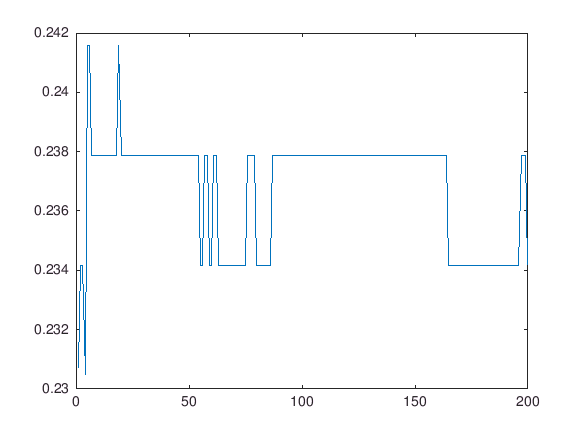

DA.fsDiscr = mdlFS;
% Ensemble Learning
mdlEL = fitensemble(trainData,responseVar,'Bag',200,'Discriminant');
figure
plot(loss(mdlEL,testData,'mode','cumulative'));

[err,idx] = min(loss(mdlEL,testData,'mode','cumulative'))

err = 0.2305

idx = 4

DA.elDiscr = mdlEL;
% Multiclass Method
template = templateDiscriminant('DiscrimType','linear');
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)

err = 0.2343

errCV = 0.1875

mdl =   ClassificationECOC
           PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationDiscriminant]}
               CodingName: 'onevsone'


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.2343

errCV = 0.1875

DA.mcDiscr = mdl;

- SVM

%%Fit
mdl = fitcsvm(trainData,responseVar,'kernelFunction','gaussian','Standardize',1);
DA.cSVM = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.2005

% Cross Validation
kFold = 5;
mdlCV = fitcsvm(trainData,responseVar,'kFold',kFold,'KernelFunction','gaussian','Standardize',1);
errCV = kfoldLoss(mdlCV)

errCV = 0.1715


%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitcsvm)

mdlPCA =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624
                    Alpha: [407×1 double]
                     Bias: 0.3725
         KernelParameters: [1×1 struct]
                       Mu: [-0.4163 0.3072]
                    Sigma: [46.3013 13.0682]
           BoxConstraints: [624×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [624×1 logical]
                   Solver: 'SMO'


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3415

errCV = 0.2981

DA.pcaCSVM = mdlPCA;
% Feature Seletion
[mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitcsvm)

ans = cell
    'Fare'


mdlFS =   ClassificationSVM
           PredictorNames: {'Fare'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 624
                    Alpha: [417×1 double]
                     Bias: 0.5276
         KernelParameters: [1×1 struct]
                       Mu: 31.7800
                    Sigma: 46.2704
           BoxConstraints: [624×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [624×1 logical]
                   Solver: 'SMO'


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'Fare'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.3692

errCV = 0.3237

DA.fsCSVM = mdlFS;
% Multiclass Method
template = templateSVM('KernelFunction','gaussian','Standardize',1);
[mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)

err = 0.2005

errCV = 0.2003

mdl =   ClassificationECOC
           PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationSVM]}
               CodingName: 'onevsone'


  Properties, Methods


mdlCV =   classreg.learning.partition.ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'Pclass'  'Sex'  'Age'  'SibSp'  'Parch'  'Fare'  'Embarked'  'AgeGroup'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


err = 0.2005

errCV = 0.2003

DA.mcCSVM = mdl;

Regression

- Multiple Linear Regression

%%Fit
mdl = fitlm(data,'linear','ResponseVar',responseVar);

%%Evaluate
% Display
mdl

mdl = 
Linear regression model:
    Survived ~ 1 + Pclass + Sex + Age + SibSp + Parch + Fare + Embarked + AgeGroup

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        2.0336       0.1036      19.63     1.824e-71
    Pclass           -0.16018     0.019881     -8.057    2.5295e-15
    Sex              -0.50738       0.0279    -18.185     5.304e-63
    Age             -0.003006     0.001514    -1.9855      0.047399
    SibSp           -0.046068     0.013137    -3.5068    0.00047649
    Parch           -0.028228     0.018556    -1.5212       0.12856
    Fare           0.00035948    0.0003284     1.0946       

% ANOVA
anova(mdl)

ans = 9×5 table
                 SumSq     DF     MeanSq       F         pValue  
                _______    ___    _______    ______    __________

    Pclass       9.2664      1     9.2664    64.915    2.5295e-15
    Sex          47.207      1     47.207    330.71     5.304e-63
    Age         0.56273      1    0.56273    3.9422      0.047399
    SibSp        1.7554      1     1.7554    12.297    0.00047649
    Parch       0.33033      1    0.33033    2.3141       0.12856
    Fare        0.17104      1    0.17104    1.1982       0.27398
    Embarked    0.66779      1    0.66779    4.6782      0.030815
    AgeGroup    0.97632      1    0.97632    6.8396     0.0090682
    Error

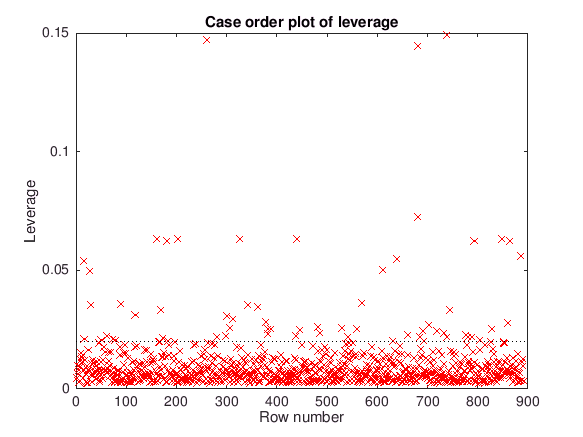

% Diagnostics Plot
plotDiagnostics(mdl)

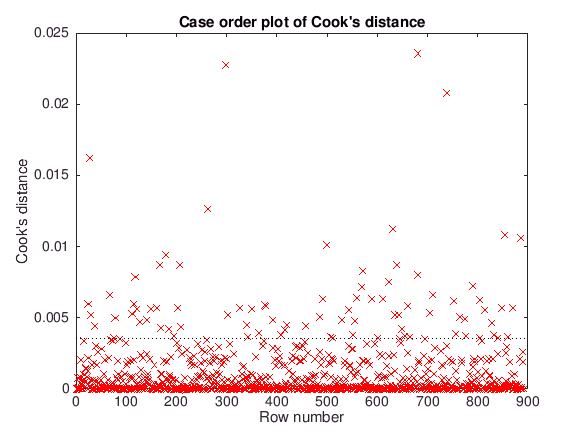

plotDiagnostics(mdl,'Cookd')

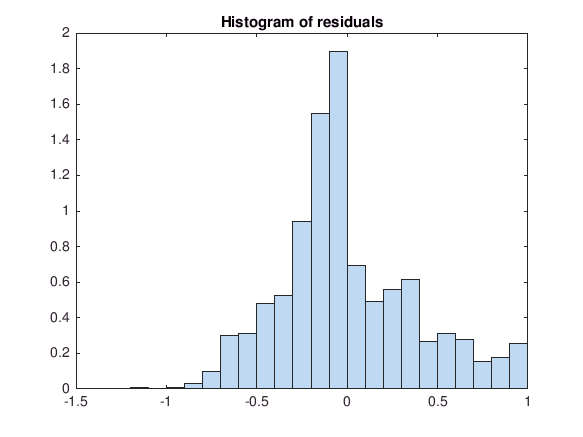

% Residuals Plot
plotResiduals(mdl)

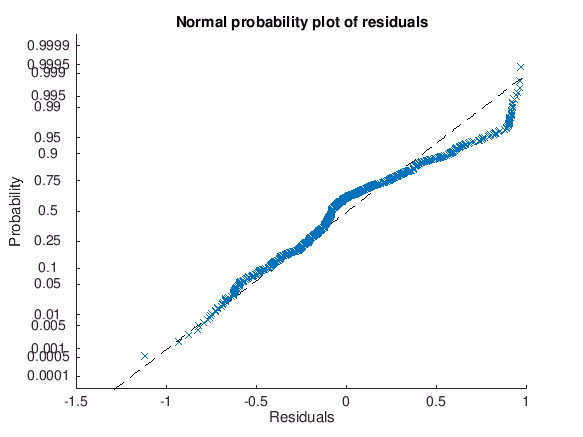

plotResiduals(mdl,'probability')

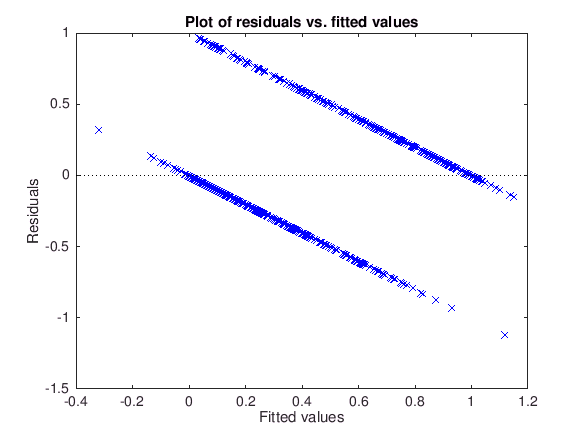

plotResiduals(mdl,'fitted')

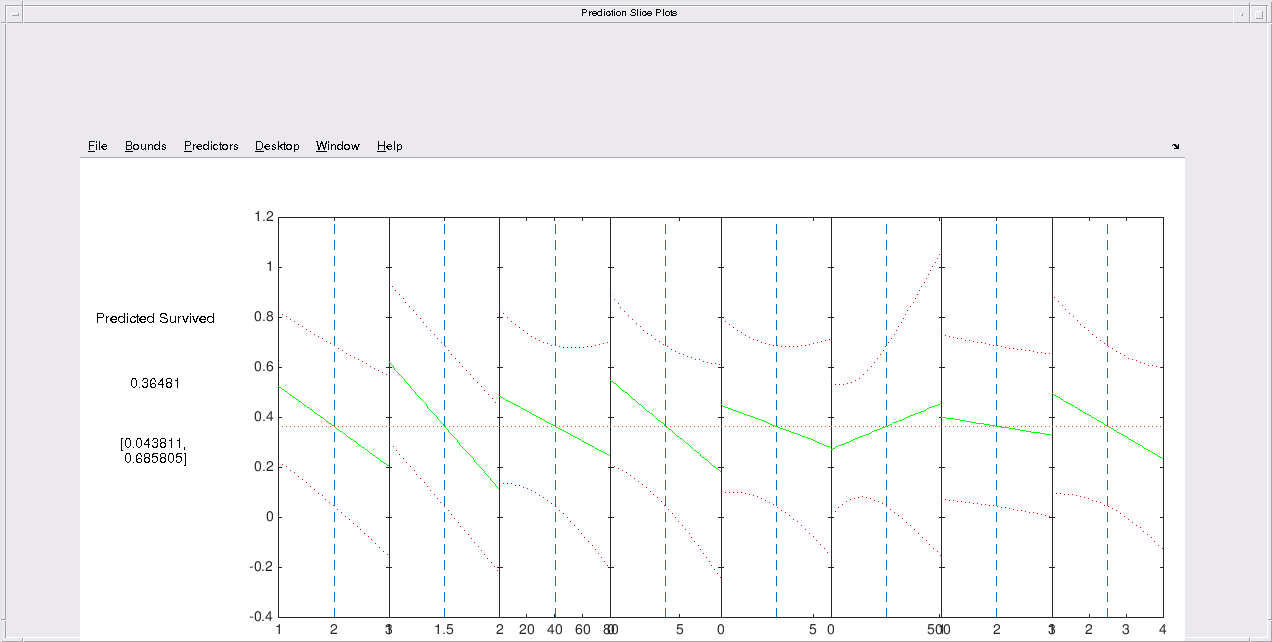

% Predictor Effects
plotSlice(mdl)

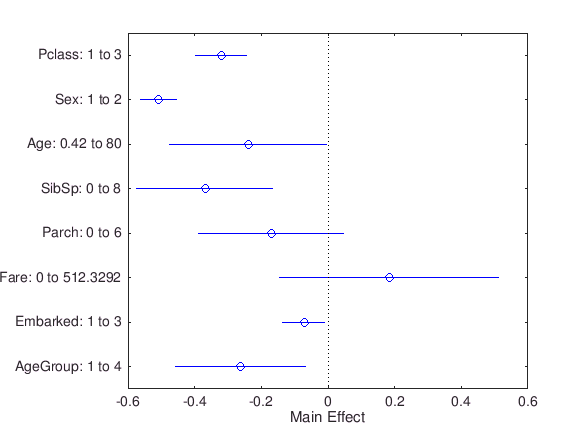

plotEffects(mdl)


%%Update
% Remove outliers
outIdxD = mdl.Diagnostics.CooksDistance>0.015;
outIdxR = mdl.Residuals.Raw <-1;
mdl = fitlm(data,'linear','ResponseVar',responseVar,'Exclude',outIdxD & outIdxR)

mdl = 
Linear regression model:
    Survived ~ 1 + Pclass + Sex + Age + SibSp + Parch + Fare + Embarked + AgeGroup

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        2.0523      0.10332     19.864     7.573e-73
    Pclass           -0.16195       0.0198    -8.1793    9.9192e-16
    Sex              -0.50873     0.027778    -18.314    9.8371e-64
    Age            -0.0031052    0.0015075    -2.0599      0.039704
    SibSp           -0.047659     0.013088    -3.6414    0.00028702
    Parch           -0.026623      0.01848    -1.4406       0.15005
    Fare           0.00041255    0.0003274     1.2601       


DA.LR = mdl;

- Stepwise Linear Regression

%%Fit
mdl = stepwiselm(data,'linear','ResponseVar',responseVar);

1. Adding Sex:AgeGroup, FStat = 18.6083, pValue = 1.78673e-05
2. Adding Pclass:Sex, FStat = 11.6326, pValue = 0.000677565
3. Adding Age:AgeGroup, FStat = 9.4633, pValue = 0.0021612
4. Adding Age:SibSp, FStat = 16.8451, pValue = 4.4336e-05
5. Adding Age:Parch, FStat = 6.2958, pValue = 0.012282
6. Adding Sex:Fare, FStat = 6.3778, pValue = 0.011731
7. Adding Age:Embarked, FStat = 4.3719, pValue = 0.036825
8. Adding Age:Fare, FStat = 5.3762, pValue = 0.020643



%%Evaluate
% Display
mdl

mdl = 
Linear regression model:
    Survived ~ 1 + Pclass*Sex + Sex*Fare + Sex*AgeGroup + Age*SibSp + Age*Parch + Age*Fare + Age*Embarked + Age*AgeGroup

Estimated Coefficients:
                     Estimate         SE         tStat       pValue  
                    __________    __________    _______    __________

    (Intercept)         2.2878       0.30855     7.4149    2.8769e-13
    Pclass            -0.43593      0.067993    -6.4114    2.3573e-10
    Sex               -0.35325       0.17095    -2.0665       0.03908
    Age              -0.031168      0.007048    -4.4222       1.1e-05
    SibSp             -0.16703       0.02917    -5.7261    1.4126e-08
    Parch               0.1321      0.052313     2.5251      0.011742
    Fare       

% ANOVA
anova(mdl)

ans = 17×5 table
                     SumSq      DF      MeanSq        F         pValue  
                    ________    ___    ________    _______    __________

    Pclass            7.7934      1      7.7934     59.153    3.9269e-14
    Sex                44.54      1       44.54     338.07    4.4307e-64
    Age              0.35838      1     0.35838     2.7201      0.099448
    SibSp             2.4159      1      2.4159     18.337    2.0555e-05
    Parch            0.41298      1     0.41298     3.1346      0.076998
    Fare            0.051654      1    0.051654    0.39206       0.53138
    Embarked         0.69331      1     0.69331     5.2623      0.022028
    AgeGroup       

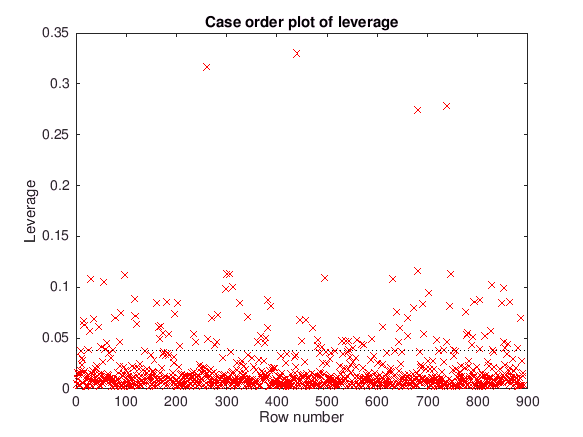

% Diagnostics Plot
plotDiagnostics(mdl)

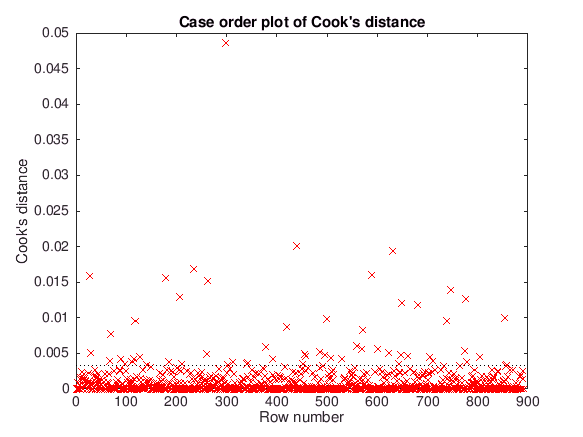

plotDiagnostics(mdl,'Cookd')

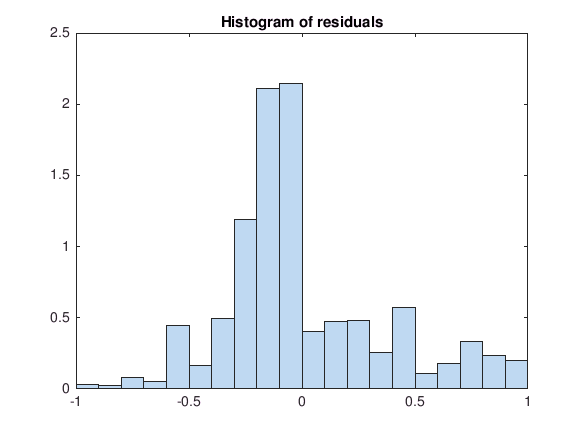

% Residuals Plot
plotResiduals(mdl)

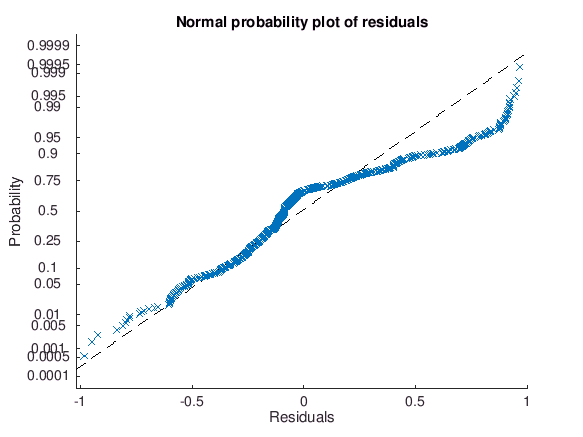

plotResiduals(mdl,'probability')

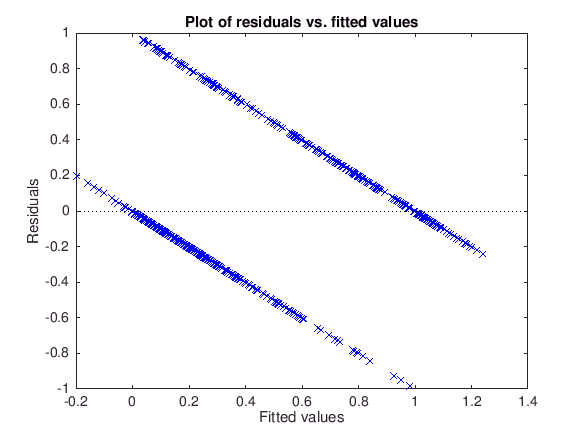

plotResiduals(mdl,'fitted')

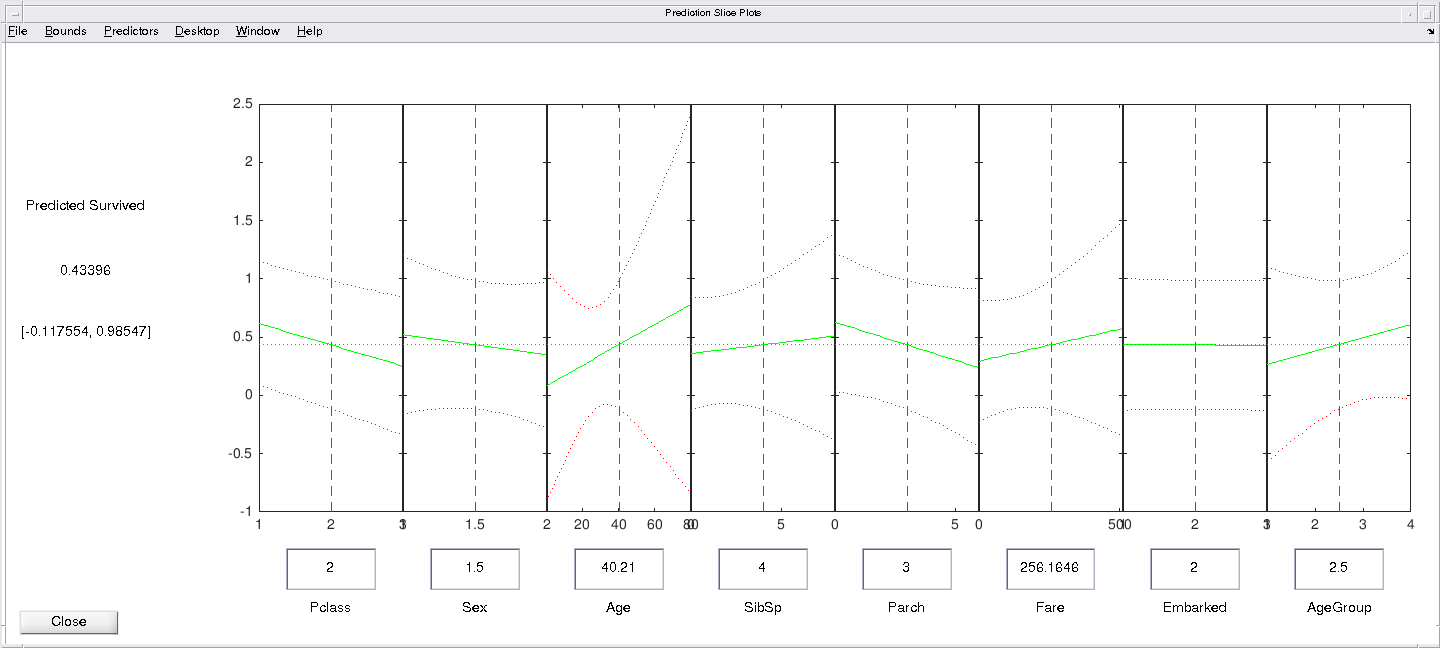

% Predictor Effects
plotSlice(mdl)

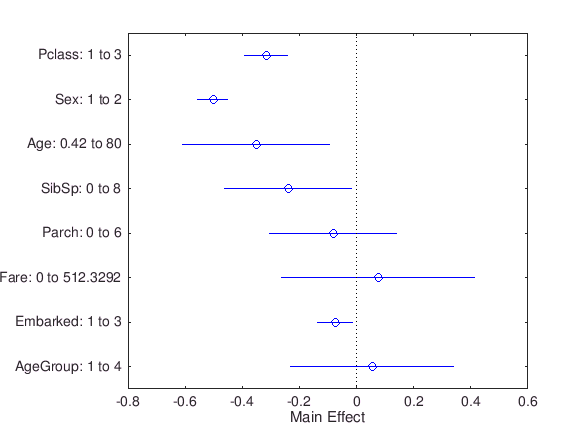

plotEffects(mdl)


%%Update
% Remove outliers

DA.SLR = mdl;

- Regularized Linear Regression (Ridge Regression)

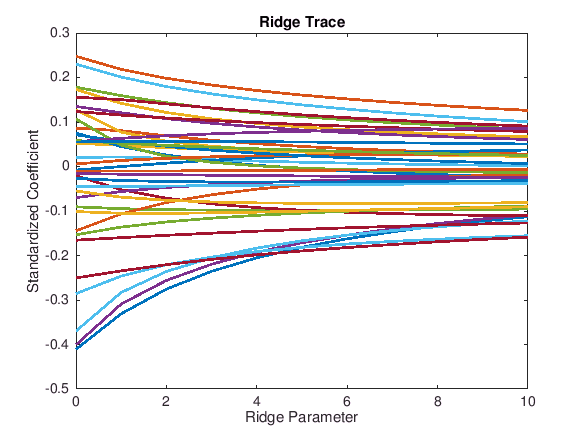

%%Fit
lambda = 0:10;
D = x2fx(data{:,predictVars},'interaction');
D(:,1) = [];
mdl = ridge(data{:,responseVar},D,lambda);

%%Evaluate
% Display
figure
plot(lambda,mdl,'LineWidth',2)
xlabel('Ridge Parameter')
ylabel('Standardized Coefficient')
title('Ridge Trace')

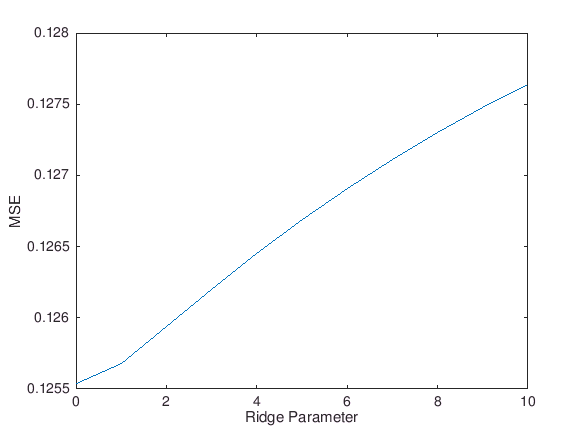

% Mean Squared Error
yTest =  predictRidgeResponse(mdl,D,D,data{:,responseVar});
mse = mean((data{:,responseVar}-yTest).^2);
figure
plot(lambda,mse)
xlabel('Ridge Parameter')
ylabel('MSE')

title('Ridge MSE')

%%Update
% Choose the lambda with smallest mse
[~,idx] = min(mse);
mdl = ridge(data{:,responseVar},D,lambda(idx));

DA.RidgeR = mdl;

- Regularized Linear Regression (Lasso Regression)

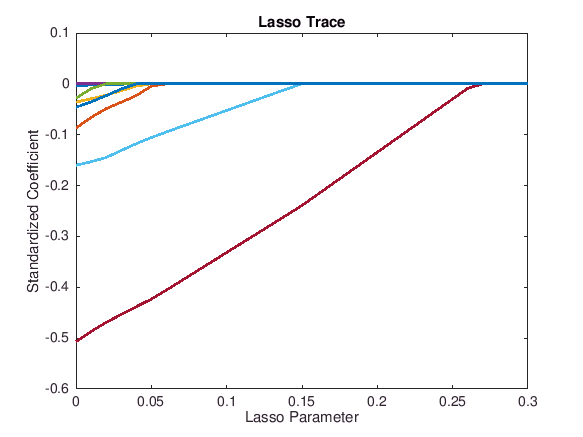

%%Fit
numLambda = 25;
kFold = 5;
[mdl,fitInfo] = lasso(data{:,predictVars},data{:,responseVar},'NumLambda',numLambda,'CV',kFold);

%%Evaluate
% Display
figure
lassoPlot(mdl,fitInfo,'PlotType','CV');
figure
lassoPlot(mdl,fitInfo,'PlotType','Lambda','XScale','log');

% figure
% plot(lambda,mdl,'LineWidth',2)
% xlabel('Lasso Parameter')
% ylabel('Standardized Coefficient')
% title('Lasso Trace')

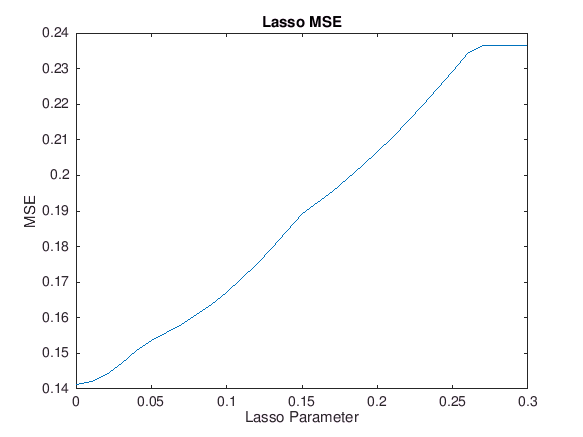

% % Mean Squared Error
% figure
% plot(lambda,fitInfo.MSE)
% xlabel('Lasso Parameter')
% ylabel('MSE')
% title('Lasso MSE')


%%Update
% Choose the lambda with smallest mse
[~,idx] = min(fitInfo.MSE);
mdl = lasso(data{:,predictVars},data{:,responseVar},'Lambda',lambda(idx));

DA.LassoR = mdl;

- Generalized Linear Regression (Logistic Regression)

%%Fit
mdl = fitglm(data,'interactions','ResponseVar',responseVar,'Distribution','binomial')

%%Evaluate
% Display
mdl
% Diagnostics Plot
plotDiagnostics(mdl)
plotDiagnostics(mdl,'Cookd')
% Residuals Plot
plotResiduals(mdl)
plotResiduals(mdl,'probability')
plotResiduals(mdl,'fitted')
% Predictor Effects
plotSlice(mdl)

%%Update
% Remove outliers
outIdxD = mdl.Diagnostics.CooksDistance>0.015;
mdl = fitglm(data,'interactions','ResponseVar',responseVar,'Exclude',outIdxD)

DA.GLR = mdl;

- Generalized Linear Regression (Regularized Logistic Regression)

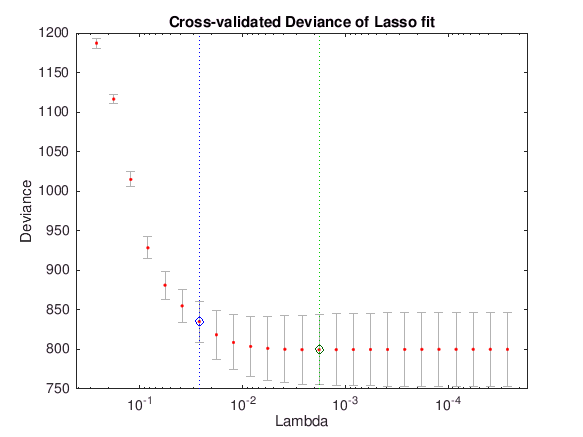

%%Fit
numLambda = 25;
kFold = 5;
[mdl,fitInfo] = lassoglm(data{:,predictVars},data{:,responseVar},'binomial','NumLambda',25,'CV',kFold);

%%Evaluate
% Display
figure
lassoPlot(mdl,fitInfo,'PlotType','CV');

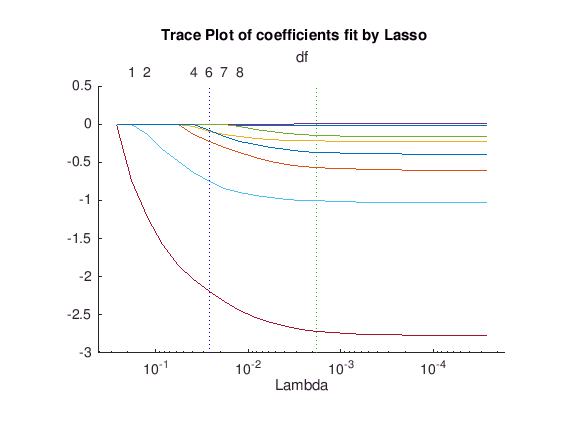

figure
lassoPlot(mdl,fitInfo,'PlotType','Lambda','XScale','log');

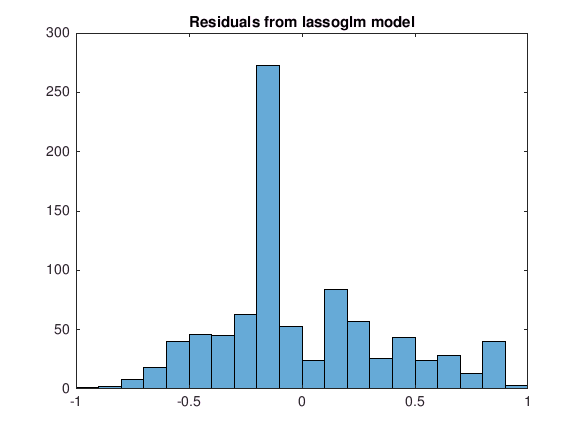


%%Update
% Choose the lambda with minimum deviance plus one standard deviation point
idx = FitInfo.Index1SE;
mdl1 = mdl(:,idx);
cnst = FitInfo.Intercept(idx);
mdl2 = [cnst;mdl1];

DA.LassoGLR = mdl2;

- Regression Tree

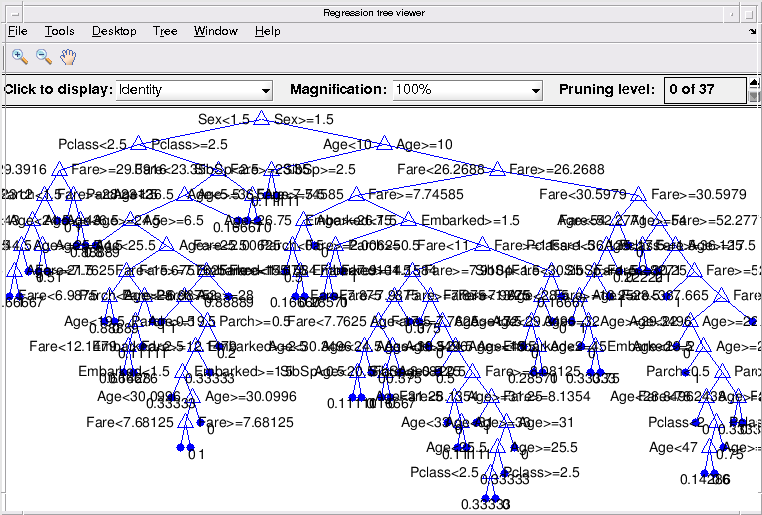

%%Fit
mdl = fitrtree(trainData,responseVar);
view(mdl,'mode','graph')

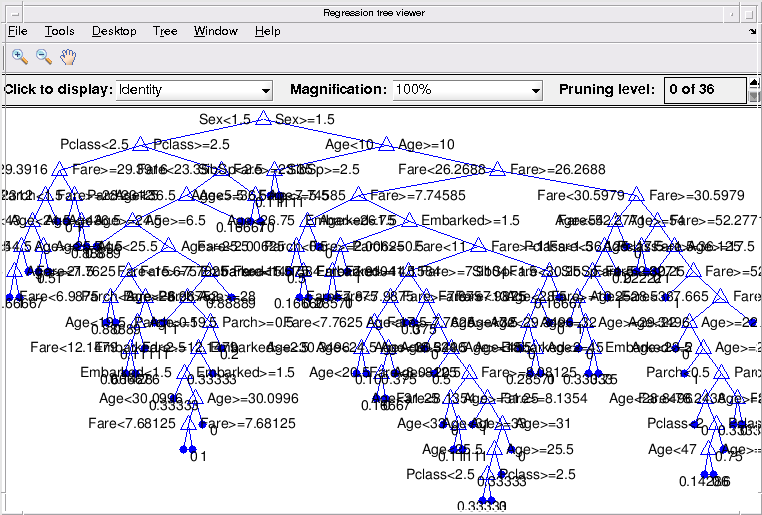

% Prune the tree
mdlPrune = prune(mdl,'Level',1);
view(mdlPrune,'mode','graph')

DA.rTree = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.1703

err = loss(mdlPrune,testData)

err = 0.1703

% Cross Validation
kFold = 5;
mdlCV = fitrtree(trainData,responseVar,'kFold',kFold);
errCV = kfoldLoss(mdlCV)

errCV = 0.1658


%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitrtree)

mdlPCA =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 624


  Properties, Methods


mdlCV =   classreg.learning.partition.RegressionPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
      ResponseTransform: 'none'


  Properties, Methods


err = 0.2782

errCV = 0.2943

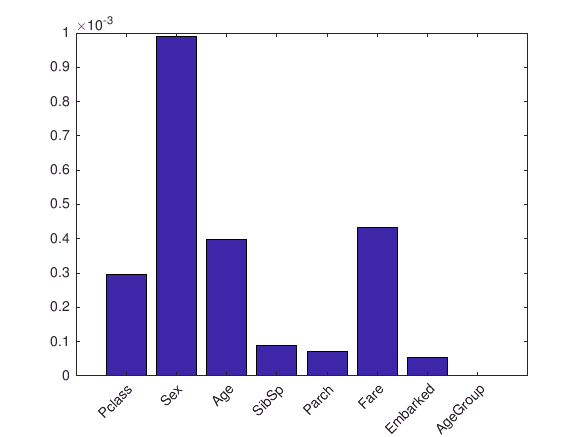

DA.pcaRTree = mdlPCA;
% Feature Importance
figure
p = predictorImportance(mdl);
bar(p);
ax = gca;
ax.XTickLabel = mdl.PredictorNames;
ax.XTickLabelRotation = 45;

toKeep = p>0.5e-3;
mdlFI = fitrtree(trainData{:,toKeep},trainData{:,responseVar});
err = loss(mdlFI,testData{:,toKeep},testData{:,responseVar})

err = 0.2096

DA.fiRTree = mdlFI;
% Feature Selection
[mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitrtree)

ans = 1×4 cell array
    'Survived'    'Age'    'Parch'    'Fare'


mdlFS =   RegressionTree
           PredictorNames: {'Age'  'Fare'  'Parch'}
             ResponseName: 'Survived'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 624


  Properties, Methods


mdlCV =   classreg.learning.partition.RegressionPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'Age'  'Fare'  'Parch'}
           ResponseName: 'Survived'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
      ResponseTransform: 'none'


  Properties, Methods


err = 0.2948

errCV = 0.2943

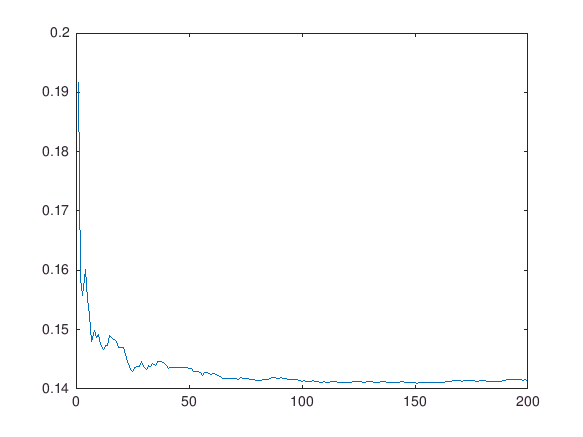

DA.fsRTree = mdlFS;
% Ensemble Learning
mdlEL = fitensemble(trainData,responseVar,'Bag',200,'Tree','Type','regression');
figure
plot(loss(mdlEL,testData,'mode','cumulative'));

[err,idx] = min(loss(mdlEL,testData,'mode','cumulative'))

err = 0.1410

idx = 151

DA.elRTree = mdlEL;

- SVM Regression 

%%Fit
mdl = fitrsvm(trainData,responseVar,'kernelFunction','gaussian','Standardize',1);
DA.rSVM = mdl;

%%Evaluate
% Model Performence
err = loss(mdl,testData)

err = 0.1641

% Cross Validation
kFold = 5;
mdlCV = fitrsvm(trainData,responseVar,'kFold',kFold,'KernelFunction','gaussian','Standardize',1);
errCV = kfoldLoss(mdlCV)

errCV = 0.1606


%%Update
% PCA
[mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,@fitrsvm)

mdlPCA =   RegressionSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [418×1 double]
                     Bias: 0.6168
         KernelParameters: [1×1 struct]
                       Mu: [-0.4163 0.3072]
                    Sigma: [46.3013 13.0682]
          NumObservations: 624
           BoxConstraints: [624×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [624×1 logical]
                   Solver: 'SMO'


  Properties, Methods


mdlCV =   classreg.learning.partition.RegressionPartitionedSVM
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 624
                  KFold: 10
              Partition: [1×1 cvpartition]
      ResponseTransform: 'none'


  Properties, Methods


err = 0.2704

errCV = 0.2501

DA.pcaRSVM = mdlPCA;
% Feature Seletion
[mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,@fitrsvm)
DA.fsRSVM = mdlFS;

- Gaussian Process Regression

mdl = 
Generalized linear regression model:
    logit(Survived) ~ 1 + Pclass*Sex + Pclass*Age + Pclass*SibSp + Pclass*Parch + Pclass*Fare + Pclass*Embarked + Pclass*AgeGroup + Sex*Age + Sex*SibSp + Sex*Parch + Sex*Fare + Sex*Embarked + Sex*AgeGroup + Age*SibSp + Age*Parch + Age*Fare + Age*Embarked + Age*AgeGroup + SibSp*Parch + SibSp*Fare + SibSp*Embarked + SibSp*AgeGroup + Parch*Fare + Parch*Embarked + Parch*AgeGroup + Fare*Embarked + Fare*AgeGroup + Embarked*AgeGroup
    Distribution = Binomial

Estimated Coefficients:
                          Estimate         SE           tStat        pValue 
                         __________    __________    ___________    ________

    (Intercept)              12.054        6.9752         1.7281    0.083969
    Pclass                  -4.2092        1.8622        -2.2604    0.0

mdl = 
Generalized linear regression model:
    logit(Survived) ~ 1 + Pclass*Sex + Pclass*Age + Pclass*SibSp + Pclass*Parch + Pclass*Fare + Pclass*Embarked + Pclass*AgeGroup + Sex*Age + Sex*SibSp + Sex*Parch + Sex*Fare + Sex*Embarked + Sex*AgeGroup + Age*SibSp + Age*Parch + Age*Fare + Age*Embarked + Age*AgeGroup + SibSp*Parch + SibSp*Fare + SibSp*Embarked + SibSp*AgeGroup + Parch*Fare + Parch*Embarked + Parch*AgeGroup + Fare*Embarked + Fare*AgeGroup + Embarked*AgeGroup
    Distribution = Binomial

Estimated Coefficients:
                          Estimate         SE           tStat        pValue 
                         __________    __________    ___________    ________

    (Intercept)              12.054        6.9752         1.7281    0.083969
    Pclass                  -4.2092        1.8622        -2.2604    0.0

mdl = 
Generalized linear regression model:
    Survived ~ 1 + Pclass*Sex + Pclass*Age + Pclass*SibSp + Pclass*Parch + Pclass*Fare + Pclass*Embarked + Pclass*AgeGroup + Sex*Age + Sex*SibSp + Sex*Parch + Sex*Fare + Sex*Embarked + Sex*AgeGroup + Age*SibSp + Age*Parch + Age*Fare + Age*Embarked + Age*AgeGroup + SibSp*Parch + SibSp*Fare + SibSp*Embarked + SibSp*AgeGroup + Parch*Fare + Parch*Embarked + Parch*AgeGroup + Fare*Embarked + Fare*AgeGroup + Embarked*AgeGroup
    Distribution = Normal

Estimated Coefficients:
                          Estimate          SE         tStat        pValue  
                         ___________    __________    ________    __________

    (Intercept)               2.2985       0.63197       3.637    0.00029267
    Pclass                  -0.45408         0.175     -2.5947     0.0096322
   

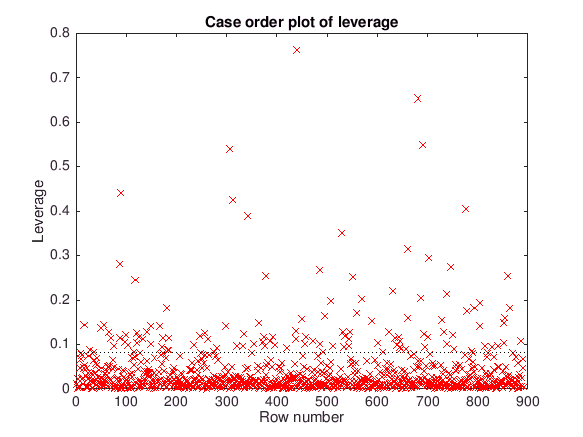

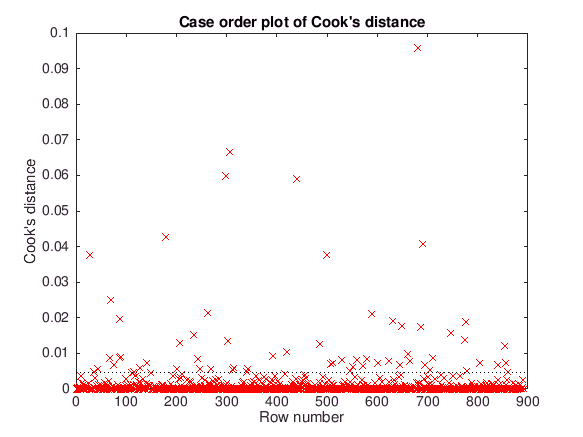

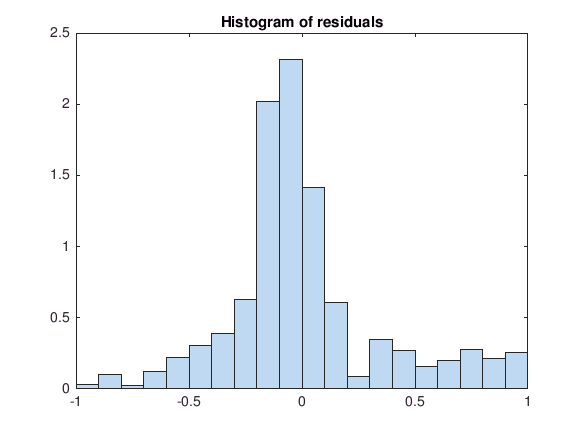

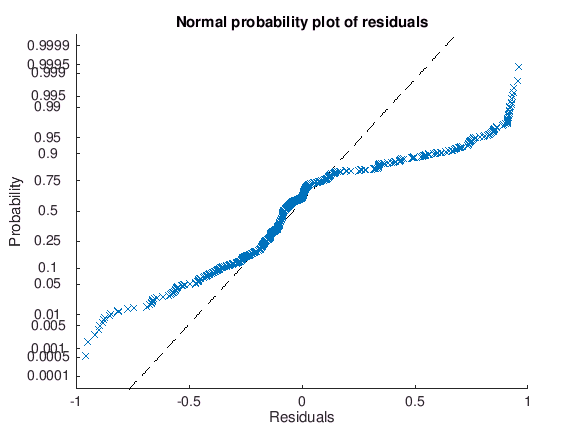

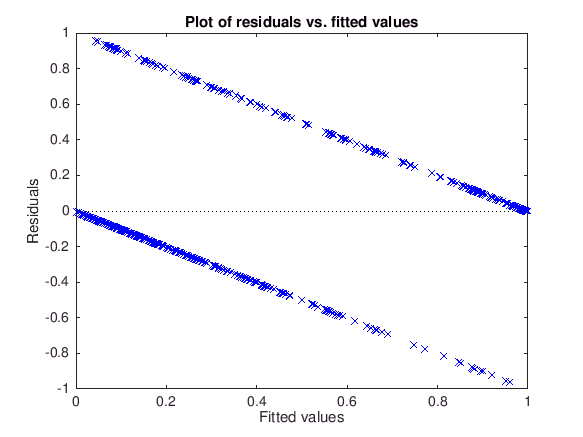

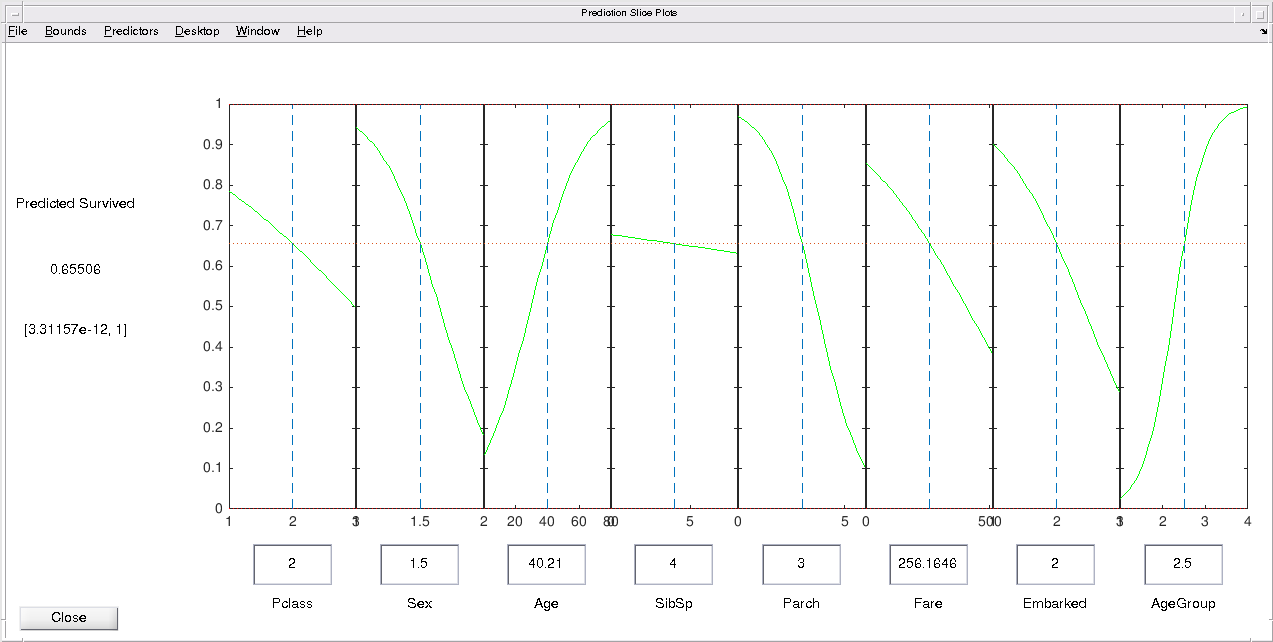

Neural Networks

## Make Predictions

% Predict classification model
cMdl = predict(DA.NB,predictData)
% Predict classification PCA model
cPCA = predict(DA.pcaNB,pcaPredictData)
% Predict regression model
rL = predict(DA.LR,predictData{:,:})
% Predict ridge regression model
ridgePredictData = x2fx(predictData{:,:},'interaction');
ridgePredictData(:,1) = [];
rRidge = predictRidgeResponse(DA.RidgeR,ridgePredictData,D,data{:,responseVar})

rRidge =   -12.7904
  -13.7017
  -25.2481
  -10.7263
  -10.4945
   -5.1439
   -9.7514
  -26.1366
   -5.1038
  -18.2255


% Predict lasso logistic regression model
rLassoGLR = glmval(DA.LassoGLR,predictData{:,:},'logit')

## **Function Define**

function [mdlPCA,mdlCV,err,errCV] = pcaFun(pcaTrain,pcaTrainResponse,pcaTest,pcaTestResponse,fitFun)   
    % PCA Function
    
    if(isequal(fitFun,@fitcknn)) 
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'NumNeighbors',5,'Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'NumNeighbors',5,'Standardize',1,'crossval','on');
    elseif(isequal(fitFun,@fitctree))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitcnb))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'Distribution','normal');
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','Distribution','normal');
    elseif(isequal(fitFun,@fitcdiscr))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'DiscrimType','linear');
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','DiscrimType','linear');
    elseif(isequal(fitFun,@fitcsvm))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','KernelFunction','gaussian','Standardize',1);
    elseif(isequal(fitFun,@fitcecoc))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitrtree))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on');
    elseif(isequal(fitFun,@fitrsvm))
        mdlPCA = fitFun(pcaTrain,pcaTrainResponse,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(pcaTrain,pcaTrainResponse,'crossval','on','KernelFunction','gaussian','Standardize',1);
    end
    err = loss(mdlPCA,pcaTest,pcaTestResponse);
    errCV = kfoldLoss(mdlCV);  
end


function [mdlFS,mdlCV,err,errCV] = fsFun(data,predictVars,responseVar,trainData,testData,kFold,vars,fitFun)
    % Feature Select Function
    
    errorFun = @(Xtrain,ytrain,Xtest,ytest) nnz(ytest ~= predict(fitFun(Xtrain,ytrain),Xtest));
    toKeep = sequentialfs(errorFun,data{:,predictVars},data{:,responseVar},'cv',kFold);
    vars(toKeep)
    if(isequal(fitFun,@fitcknn)) 
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'NumNeighbors',5,'Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'NumNeighbors',5,'Standardize',1,'crossval','on');
    elseif(isequal(fitFun,@fitctree))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitcnb))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'Distribution','normal');
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','Distribution','normal');
    elseif(isequal(fitFun,@fitcdiscr))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'DiscrimType','linear');
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','DiscrimType','linear');
    elseif(isequal(fitFun,@fitcsvm))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','KernelFunction','gaussian','Standardize',1);
    elseif(isequal(fitFun,@fitcecoc))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitrtree))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on');
    elseif(isequal(fitFun,@fitrsvm))
        mdlFS = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'KernelFunction','gaussian','Standardize',1);
        mdlCV = fitFun(trainData(:,union(vars(toKeep),responseVar)),responseVar,'crossval','on','KernelFunction','gaussian','Standardize',1);
    end
    err = loss(mdlFS,testData);
    errCV = kfoldLoss(mdlCV);  
end

function [mdl,mdlCV,err,errCV] = mcFun(trainData,testData,responseVar,template,kFold)
    % Multiclass Function   
    mdl = fitcecoc(trainData,responseVar,'Learners',template);
    err = loss(mdl,testData)
    mdlCV = fitcecoc(trainData,responseVar,'Learners',template,'kFold',kFold);
    errCV = kfoldLoss(mdlCV) 
end

function yPred =  predictRidgeResponse(mdl,xTest,xTrain,yTrain)
    % Make predictions
    % To make predictions with original data, need to shift coefficients back
    % to unscaled data (RIDGE normalizes data by default)
    m = mean(xTrain);
    s = std(xTrain,0,1)';   
    % (un)Scale b
    bUS = bsxfun(@rdivide,mdl,s);
    % Calculate constant term (from scaling)
    intercept = mean(yTrain)-m*bUS;
    % Make predictions
    yPred = xTest*bUS+intercept;
end